clc,clear,close all;
T=readtable("data_corrected_2.csv")

T = 519039×8 table
              x__              x____    x___1    x_____1    x___2    x_____2    x___3     x___4
    _______________________    _____    _____    _______    _____    _______    ______    _____

    {'05/09/2014 14:16:21'}     26      -9999     2411        0       45340     691.47      0  
    {'05/09/2014 14:16:22'}     26      -9999     2411        0       42623     691.47      0  
    {'05/09/2014 14:16:23'}     26      -9999     2411        0       39907     691.47      0  
    {'05/09/2014 14:16:24'}     26      -9999     2411        0       37190     691.47      0  
    {'05/09/2014 14:16:25'}     26      -9999     2411        0       34474     691.47      0  
    {'05/09/2014 14:16:26'}     26      -9999     2411        0       35453     694.18      0  
    {'05/09/2014 14:16:27'}     26      -9999     2411        0       36432     696.89      0  
    {'05/09/2014 14:16:28'}     26      -9999     2411        0       37411      699.6      0  
    {'05/09/2014 14:

%钻深
bit_depth=table2array(T(:,2));
%钻压
%WOB=table2array(T(:,3));
%井眼深度
hole_depth=table2array(T(:,4));
%流速
%f=table2array(T(:,5));
%立管压力
%psi=table2array(T(:,6));
%扭矩
%torque=table2array(T(:,7));
%转速
%w=table2array(T(:,8));

%add=f.*f.*bit_depth;
%add2=f.*f;
%value={'钻头深度','钻压','井眼深度','流速','立管压力','转速','扭矩','流方井深','流方'}
%T0=table(bit_depth,WOB,hole_depth,f,psi,torque,w,add,add2,VariableNames=value);
a=hole_depth-bit_depth;
sorteda=sort(a);
sorteda = sorteda(find(sorteda > 0))

sorteda = 1.0e+03 *

    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


plot(sorteda,'LineWidth',1.5,'Color',[0.36078 0.67451 0.93333]);
xlabel('dataIndex')
ylabel('deltaDepth')
title("DeltaDepth-index")
hold on
index1=find(sorteda==500)

index1 =       269742
      269743
      269744
      269745
      269746
      269747
      269748


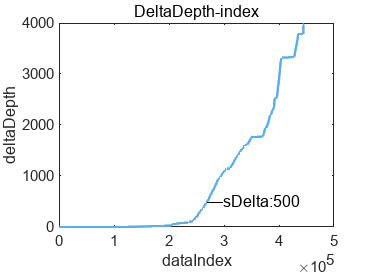

text(index1(1,1),500,"—sDelta:500");
saveas(gcf,"sort2.png");%50需要改


%T1=T0(index1,:);
%writetable(T1,"data3_not_in.csv");
%T2=T0(index2,:);
%writetable(T2,"data3_in_.csv");